# Assignment 4.3: EPO4, Module 2, Voice Processing

# (Only Task 1)

***Important Note:*** *Dear students, *

*Note that this script only includes task . Task 2 is  just repeating the same steps you do here with your own recorded voice, so no step by step guide is necessary.*

*Here, in this live script, we have tried to guid you through the steps you need to take to complete the fthis assignment. We have included part of the code for you and you need to complete the rest of the code denoted by "% your code here ".  Uncomment those lines with % your code here and complete it with your code. *

## Task 1: Feature extraction and classification of the speech dataset

For these assignments, you will need to use the dataset "datarec_directions.mat". The dataset is already included in this file. Run the code below to load the dataset.

clear all;
close all;
load('datarec_directions.mat');

As you can see it includes This dataset contains audio signals produced by two speakers, one woman and one man. Four words were pronounced 10 times, up, down, left, and right. The sampling frequency is Fs=8000 Hz.

### Raw Signals

The first step is to put all the recording signals together.

data=[DownM,DownW,LeftM,LeftW,RightM,RightW,UpM,UpW];

Note that "data" has our raw audio signals and not the features. We have to extract the features and make our data matrix "X". We start with performing all the steps on one recording and ploting the results. Once we are done we can make a for loop and repeat this for all the recording.

i=1;
y=data(:,i);

### Normalize the audion signal

In order to have the signals  at a comparable amplitude, we normalize them by first subtracting the mean and dividing by its largest value. Note that this is different from normalizing the features and you need to do it for each recording seperately.

% normalize the signal
% remove mean
y_norm=y-mean(y);
% devide by the max abs value
y_norm=y/max(y);

%plot the signal
t=1/Fs:1/Fs:size(data,1)/Fs;
figure; plot(t,y_norm);

### remove silence

Next we have to remove the silent part in the begining and end of the data to capture the sound better. There are many algorithms that can do this task. The simplest approach is to use a fixed threshold (slightly larger than noise amplitude) and find the index of samples  in the signal whose absolute amplitude is larger than the threshold (you can use "find()"). And then keep the signal between the first "t_start" and the last index "t_ind". Complete the "RemoveSilence.m" to do so. Feel free to use any other algorithm of your choice. We also give t_start and t_end as output for plotting and comparison. Use different threshold and check which one works better, try using different recordings by changing "i".

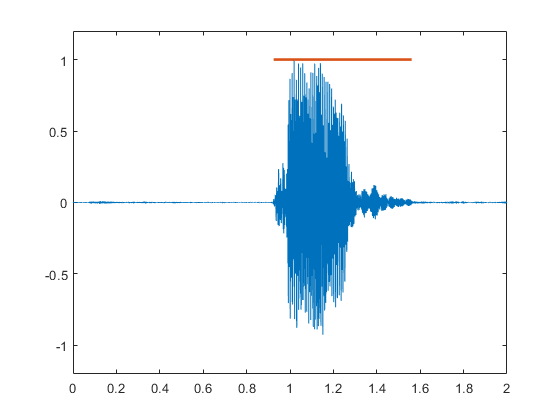

%remove silent
threshold=0.01;
[t_start,t_end,y_nosilence] = RemoveSilence(y_norm,threshold);

% denote the selected part
hold on; 
plot(t_start/Fs:1/Fs:t_end/Fs,ones(t_end-t_start+1,1),"Linewidth",2);
ylim([-1.2,1.2]); hold off; 

### Length of window and overlap

To find pitch and formant, we should first define "L":Length of the window (in samples) and "ov": Length of the overlap (in samples). First find the number of samples for a  window of 20 ms, and then set "ov" equal to half of these samples (50% overlap).

%"L":Length of the window (in samples)
L=Fs*(20/1000)

L = 160


% "ov": Length of the overlap (in samples)
ov=L*(1/2)

ov = 80

### Pitch 

complete "FindPitch.m" to find the pitch in each window

f0 = FindPitch(y_nosilence,Fs,L,ov);

### Formants

You can just use "FormantsEpo4" to find the formants.

[t_vec,frmtns] = FormantsEpo4(y_nosilence,Fs,L,ov);

### Plot Spectrograms with formants

you can use the code below to plot the spectrogram with the formants, run this for different recordings and words to see the difference in between them.

[s,f,t,ps]=spectrogram(y_nosilence, L,ov,L,Fs,'yaxis');

figure;
imagesc(t,f,10*log10(ps)); axis xy;
hold on;
length(f0)

ans = 62

length(t_vec)

ans = 62

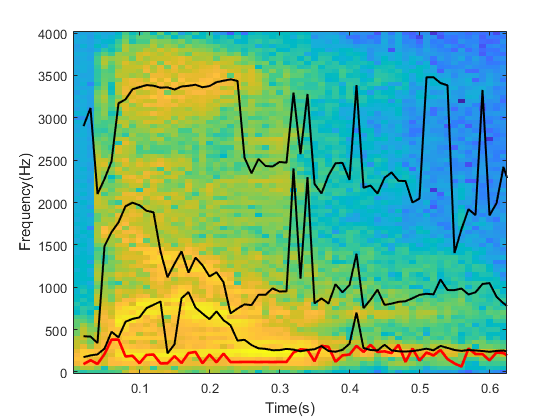

plot(t_vec,f0,'Color','red','LineWidth',2);
plot(t_vec,frmtns,'Color','black','LineWidth',1.5);
xlabel('Time(s)');ylabel('Frequency(Hz)'); hold off; 

### Feature Extraction

Let's now compute the feature which are: mean, median, and variance of the pitch and each formant. Also, compute the ratio F1/F2 and its variance. Feel free to be creative and generate your own set of features to characterize the words too! 

% mean, median, and variance of the pitch: 
% you can use nanmean(), nanmedian(), nanvar()
 x1=nanmean(f0);
 x2=nanmedian(f0);
 x3=nanvar(f0);

% mean, median, and variance of each formants
% if you set dim=1, you can find it for all three formants together
 x4=nanmean(frmtns);
 x5=nanmedian(frmtns);
 x6=nanvar(frmtns);

% mean, median, and variance of each formants
f1f2=frmtns(:,1)./frmtns(:,2); % F1/F2
 x7=nanmean(f1f2);
 x8=nanmedian(f1f2);
 x9=nanvar(f1f2);

% putting all the features together: size 1*15
x_vec=[x1,x2,x3,x4,x5,x6,x7,x8,x9];

### Repeat the steps for all recordings to make data matrix X

We can now put all the code in one matlab function in "ExtractFeat", and repeat the feature extraction for all recordings. Complete the "ExtractFeat" function. (Note that you won't need to make "VoiceProc.m" in the manual, anymore)

num_samples=size(data,2);
num_feat=15;

% matrix for recording the features
X=zeros(num_samples, num_feat);

% Extracting the features
for i=1:size(data,2)
    
    y = data(:,i);
    X(i,:)=ExtractFeat(y,Fs,L,ov,threshold);
    
end

### Labels

The rest of this assignment is repeating the same step as  in module 1. we should now make the Y matrix, the numerical labels are as follows: Down>1, Left>2, Right>3, Up>4. We had 20 recordings for each label, therefore:

Y=[ones(20,1);2.*ones(20,1);3.*ones(20,1);4.*ones(20,1)];

### Train/test split

the code we developed in the first module is now saved as a function "train_test_split" we can use it to split the dat

percent_train_split=70/100;
[train_id,test_id]=train_test_split(Y,percent_train_split);

% splitting the inputs
Xtrain=X(train_id,:);
Xtest=X(test_id,:);

% splitting the labels
Ytrain=Y(train_id,:);
Ytest=Y(test_id,:);

### Standard Normalization

Next we should performing standard normalization on train data and finding the save its mean and standard deviation, use "zscore()" function here.

[Xtrain,mu_train,sigma_train] =zscore(Xtrain);

we should perform any changes we make on training data on the test data too. using the mean and standard deviation of the training data to the test data too

Xtest=(Xtest-mu_train)./sigma_train;

### Feature Selection using mRMR

As before we can use Minimum Redundancy Maximum Relevance (mRMR) for feature extraction.

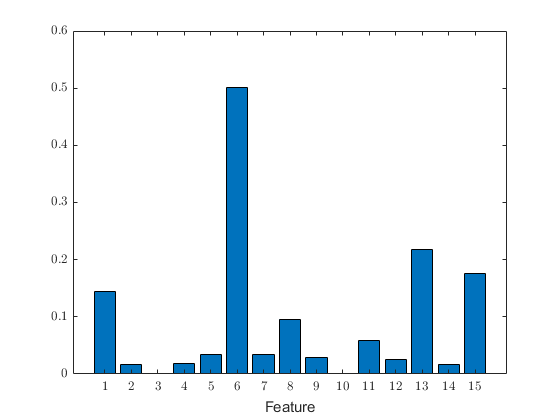

[idx,scores] =fscmrmr(X,Y);

figure;bar(idx,scores(idx))%Create bar graph
xlabel('Feature')
set(gca,'TickLabelInterpreter','latex');

ylabel('Predictor Score'); hold off;

you can select the features with higher importance for the rest of this assignment but for now we will just keep all the features.

### Training

As before we use "TreeBagger()"  with different number of trees for the classification model.

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 200;
 
% Train the TreeBagger (Random Forest).

model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

### Testing the model on test data

Ytest_pred_str = model.predict(Xtest);
Ytest_pred = str2double(Ytest_pred_str);

### Turn the numerical outputs to categorial

num_classes=length(unique(Y))

num_classes = 4

Ytest_cat=zeros(num_classes,size(Ytest,1));
Ytest_pred_cat=zeros(num_classes,size(Ytest,1));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot confusion matrix

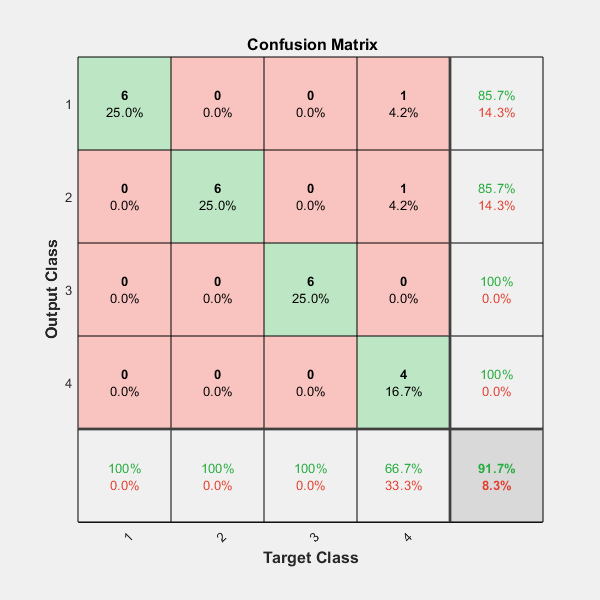

figure; plotconfusion(Ytest_cat,Ytest_pred_cat); hold off;

Run the code a couple of time as the result may vary due to random/train test split. You should be now able to answer the following questions:

- Can you have a comparable performance for the man and the woman in the data set? Note that you do not need to train one model for the man and a different one for the woman. In principle,one model should be general enough but if you test it on only samples produced by the man, theperformance might be different. Is this the case?

- What kind of sounds are easier to distinguish?

- Will the performance improve if you only select two words? If so, repeat the procedure with onlythose 2 words and report the performance.

### Test the model with your own voice: Record your voice

first you need to record yourself saying one of the direction words. run the code below to save your recording. 

**For MacOs users**: If you y output is all zero and no sound is recorded, there is an issue with the preferences granted in Mac OS. As of now, the only workaround to the issue is to open MATLAB from the terminal without using the "open" command. For most users this will look: `/Applications/MATLAB_R2019b.app/bin/matlab`

(you can select this part and next part of the code together, right click and select "evaluate selection in command widow" to record your voice, it doesn't work properly in a live script. or just copy/paste them in the command window.)

recObj = audiorecorder(Fs,16,1); % create audio object, 16 bits resolution

Error using audiorecorder/set.DeviceID (line 334)
No audio input device found on this system.

Error in audiorecorder (line 181)
            obj.DeviceID = obj.DefaultDeviceID;

disp('Start speaking...')
recordblocking(recObj, 2); % do a 2 second recording (blocking)
disp('End of Recording.');
y = getaudiodata(recObj);

### Test the model with your own voice: Predict the word

Now you can use the recording in y as your test data, first you need to extract the features, then normalize it using the mean and std of training data and finially you can use model.predict() to predict the output. Labels: Down>1, Left>2, Right>3, Up>4. We had 20 recordings for each label, therefore:

% extract feat
 x_test=ExtractFeat(y,Fs,L,ov,threshold);

% standard normalize 
 x_test=zscore(x_test);

% predic
Ytest_pred_str = model.predict(x_test);
Ytest_pred = str2double(Ytest_pred_str);

Repeat with different words and recording, How's the performance? why?

### Save your model

Incase you want to save your model for future predictions, you can use the following code.

save('mymodel.mat','model','mu_train','sigma_train');